# Ripple sEMG Verification Script

It is important to verify the integrity of the data in order to obtain reproducible results. 

This script load an `.nsx` file (e.g. `.ns2`), and plots the power spectrum profile of the entire session.

Your sEMG power spectrum should look like the image below:

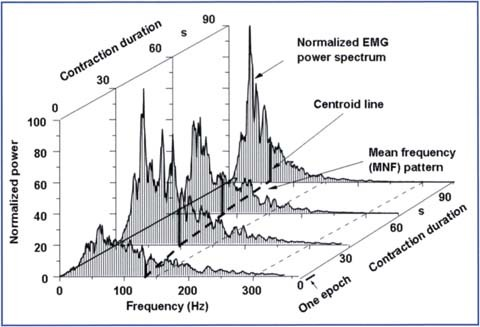

Source: Atlas of Muscle Innervation Zones by Merletti et al. (2012) [https://doi.org/10.1007/978-88-470-2463-2_5](https://doi.org/10.1007/978-88-470-2463-2_5)

## Step 1: Clear the Workspace

clear variables
clear ripple-data-validation
close all
clc

## Step 2: Load Dataset

[header, data] = read_nsx_file('File','D:\FRM\research-data\emg-fatigue\datafile0018.ns2');

Loading 0.0 GB of data


## Step 3: Retrieve Metadata

fs = header.Fs;
ch_idx = 1;
ch_signal = data(ch_idx, :);
ch_signal_init = data(ch_idx, 30*fs:90*fs )

ch_signal_init = 1×60001 int16 row vector
   -170   -178   -146   -114    -37     49    104    149    173    173    141    100     49    -24    -79   -135   -178   -191   -179   -139    -78      8     84    144    191    208    203    156    109     52    -32    -86   -140   -166   -184   -164   -126    -67     31    104    172    208    218    195    155    120     43    -14    -81   -144


ch_signal_end = data(ch_idx, end-90*fs:end -30*fs)

ch_signal_end = 1×60001 int16 row vector
   -214   -172    -93      6     82    159    177    188    140     94     36    -50   -103   -158   -206   -226   -178   -143    -78     10     80    124    165    152    122     60     -3    -80   -153   -208   -256   -249   -247   -208   -161    -95    -12     57    107    136    138    102     65     43      3    -19    -76    -99    -50      8


fprintf("Data from channel %02d sampled at %d kHz.\n%.3f sec (%02.0f mins) total.", ch_idx, fs, length(ch_signal)/fs,length(ch_signal)/fs/60);

Data from channel 01 sampled at 1000 kHz.
479.546 sec (08 mins) total.

## Step 4: Generate Power Spectrum Plot

This code was generated using the MATLAB Signal Analyzer App

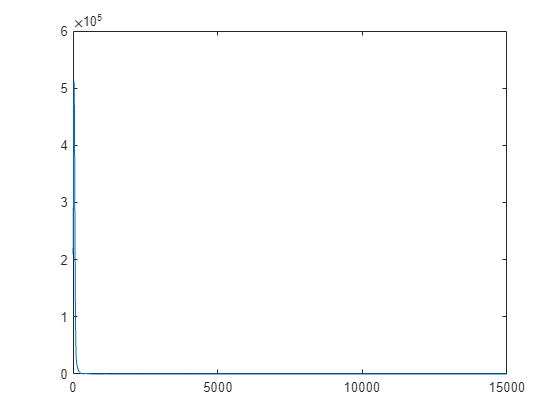

% Parameters
timeLimits = [0 (length(ch_signal)-1)/fs]; % seconds
frequencyLimits = [0 fs/2]; % Hz

% Index into signal time region of interest
ch_signal_ROI = ch_signal(:);
startTime = 0; % seconds
minIdx = ceil( max((timeLimits(1) - startTime) * fs, 0)) + 1;
maxIdx = floor( min((timeLimits(2) - startTime) * fs, length(ch_signal_ROI) -1)) + 1;
ch_signal_ROI = ch_signal_ROI(minIdx:maxIdx);

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pch_signal_ROI, Fch_signal_ROI] = pspectrum(double(ch_signal_ROI),fs, ...
    'FrequencyLimits',frequencyLimits);

plot(Fch_signal_ROI, Pch_signal_ROI)

dec_factor = 30

dec_factor = 30

ch_signal_dec = decimate(double(ch_signal), dec_factor);
fs = fs/dec_factor

fs = 1000

filt_order = 8;
f_nyq = fs /2;
fc_1 = 5;
fc_2 = 499;
[b, a] = butter(filt_order, [fc_1, fc_2]/f_nyq, 'bandpass');
ch_signal_filt = filtfilt(b, a, ch_signal_dec);

[c,l] = wavedec(ch_signal_dec,7,'haar');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3, cd4, cd5, cd6, cd7] = detcoef(c,l,[1 2 3 4 5 6 7]);

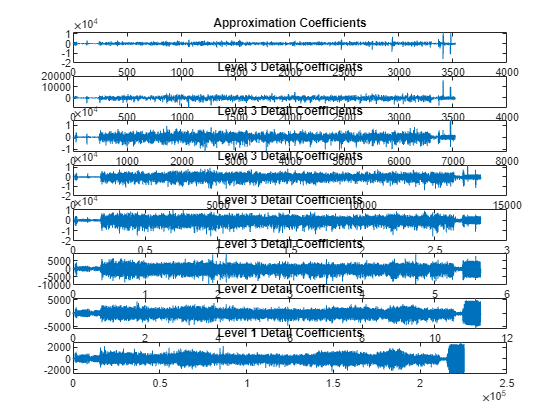

figure()
subplot(8,1,1);
plot(approx);
title('Approximation Coefficients');
subplot(8,1,2);
plot(cd7);
title('Level 3 Detail Coefficients');
subplot(8,1,3);
plot(cd6);
title('Level 3 Detail Coefficients');
subplot(8,1,4);
plot(cd5);
title('Level 3 Detail Coefficients');
subplot(8,1,5);
plot(cd4);
title('Level 3 Detail Coefficients');
subplot(8,1,6);
plot(cd3);
title('Level 3 Detail Coefficients');
subplot(8,1,7);
plot(cd2);
title('Level 2 Detail Coefficients');
subplot(8,1,8);
plot(cd1);
title('Level 1 Detail Coefficients')

## Step 5: (Optional) Use the Signal Analyzer to Further Inspect the Data

signalAnalyzer(ch_signal_end, 'SampleRate', fs)